# Reinforcement Learning for Herding Behavior in Networked Control

#### Jacob Kimball, Jonathan Zia

## Initialize Parameters

clear; clc; close all

% Define the velocity (in meters/second)
velocity = 0.1; sheep_velocity = 0.05;

% Close enough?
close_enough = 0.01;

% Delta disk size
% delta = sqrt(1.5^2 + 1); 
delta = 1.5;
epsilon = 0.75;

% Set the number of sheep
% [sheep x, sheep y, dog x, dog y]
sheep = 2; features = 2*sheep + 2;

% Set the number of training iterations
iterations = 500; test_iterations = 10;

% Set lambda for reinforcement learning
lambda = 100; forecast = 10; test_lambda = 100;

% Set placeholder for training data
% training_data = zeros(iterations*lambda, features);
% training_labels = zeros(iterations*lambda, 1);
validation_data = []; validation_labels = [];

% Set possible angles for dog trajectory
angles = [0 pi/4 pi/2 3*pi/4 pi 5*pi/4 3*pi/2, 7*pi/4];

% Specify anchor point
anchor = [-1.5; 1];
% anchor = [0, 0];

## Initialize Neural Network

% Initialize Performance metric
Reward = [];
train_performance = [];
val_performance = [];
test_performance = [];

% Choose training function
trainFcn = 'trainlm';

% Create a network
hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize, trainFcn);

% Set train/test/validation split
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% Suppress popups
net.trainParam.showWindow = 0;

% Choose performance function
net.performFcn = 'mse';

## Generate Training Data

f = waitbar(0, "Iteration 0");

% For each iteration...
for i = 1:iterations
    
    % Update waitbar
    waitbar(i/iterations, f, "Iteration " + string(i) + " of " + string(iterations));
    
    % Randomly initialize positions
    % sheep_positions = [0; 0];
    sheep_positions = [-0.25 -0.25; 0.25 0.25]';
    % dog_position = [1; -1];
    % dog_position = [rand(1); 2*rand(1) - 1];
    dog_position = [1.5*rand(1); -rand(1)];
    
    % Get initial cost
    C_init = cost(sheep_positions, anchor); C = [];
    data_batch = []; label_batch = [];
    
    % Randomness flag
    FLAG_1 = epsilon > rand(1);
    
    % Proceed lambda steps
    for j = 1:lambda
        
        % Introduce randomness for exploration
        FLAG_2 = epsilon > rand(1);
        
        % Record the current state
        validation_data = [validation_data; getState(sheep_positions, dog_position)];
            
        if net.inputs{1}.size > 0 && FLAG_2 && FLAG_1
            % Choose an angle for the dog that maximizes the expected return
            ER = zeros(size(angles));   % Initialize expected return
            % For each angle...
            for angle = 1:length(angles)
                % Move the dog by that angle
                new_state = updateState(sheep_positions, dog_position, angles(angle), velocity, sheep_velocity, delta);
                ER(angle) = net(new_state');
            end; [B, I] = max(ER); dog_angle = angles(I);
        else
            dog_angle = angles(randi([1, length(angles)])); ER = nan*ones(size(angles));
        end; Reward = [Reward; ER];
        
        [~, sheep_positions, dog_position] = ...
            updateState(sheep_positions, dog_position, dog_angle, velocity, sheep_velocity, delta);
        
        % Update cost
        C_new = cost(sheep_positions, anchor); C = [C; C_new];
        
    end
    
    % Compute validation labels for batch
    batch_labels = zeros(length(C), 1);
    for j = 1:length(batch_labels) - forecast
        batch_labels(j) = C(j) - C(j + forecast);
    end
    for j = (length(batch_labels) - (forecast - 1)):length(batch_labels)
        batch_labels(j) = C(j) - C(end);
    end; validation_labels = [validation_labels; batch_labels];
    
    % Update network
    [net, tr] = train(net, validation_data', validation_labels');

    % Test the network
    Y = net(validation_data');
    
    % Recalculate Training, Validation and Test Performance
    trainTargets = validation_labels'.*tr.trainMask{1};
    valTargets = validation_labels'.*tr.valMask{1};
    testTargets = validation_labels'.*tr.testMask{1};
    trainPerformance = perform(net, trainTargets, Y);
    valPerformance = perform(net, valTargets, Y);
    testPerformance = perform(net, testTargets, Y);
    
    train_performance = [train_performance; trainPerformance];
    val_performance = [val_performance; valPerformance];
    test_performance = [test_performance; testPerformance];
    
end; close(f)

## Testing Protocol

f = waitbar(0, "Test Iteration 0");

test_data = []; test_reward = [];

% For each iteration...
for i = 1:test_iterations
    
    % Update waitbar
    waitbar(i/test_iterations, f, "Test Iteration " + string(i) + " of " + string(test_iterations));
    
    % Randomly initialize positions
    sheep_positions = [0; 0];
    sheep_positions = [-0.25 -0.25; 0.25 0.25]';
    % dog_position = [1; -1];
    % dog_position = [rand(1); 2*rand(1) - 1];
    dog_position = [1.5*rand(1); -rand(1)];
    
    % Proceed lambda steps
    for j = 1:test_lambda
        
        % Record the current state
        test_data = [test_data; getState(sheep_positions, dog_position)];
            
        % Choose an angle for the dog that maximizes the expected return
        ER = zeros(size(angles));   % Initialize expected return
        % For each angle...
        for angle = 1:length(angles)
            % Move the dog by that angle
            new_state = updateState(sheep_positions, dog_position, angles(angle), velocity, sheep_velocity, delta);
            ER(angle) = net(new_state');
        end; [B, I] = max(ER); dog_angle = angles(I); test_reward = [test_reward; ER];
        
        [~, sheep_positions, dog_position] = ...
            updateState(sheep_positions, dog_position, dog_angle, velocity, sheep_velocity, delta);
        
    end
    
end; close(f)

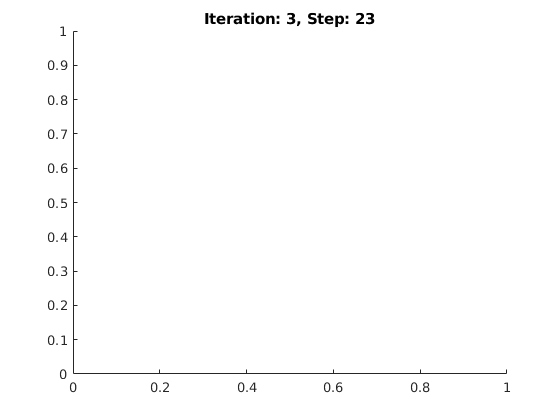

Invalid or deleted object.

Error in animate (line 40)
            s1.XData = data(j, 1); s1.YData = data(j, 3);

f = figure('visible', 'on'); hold on; grid on;
animate(test_data, test_reward, test_lambda, 1, test_iterations, sheep);